# Urban 5G Simulation

This MATLAB live script simulates an urban 5G network. It includes various sections for creating antennas, generating base stations, plotting SINR maps, analyzing coverage, examining line of sight between transmitters, finding the best transmitter, performing handover analysis, and studying network capacity.

## Antennas and their radiation patterns

In this section, we create different types of antennas and their radiation patterns. The function Create_Antennas returns four antenna objects: triangular, rectangular, circular, and a microstrip antenna. These antennas objects are stored in variables 'p_triang', 'p_rect', 'p_Circle', and 'p_mc', respectively. The function 'Plot_Antennas' is then used to visualize these antenna's patterns.

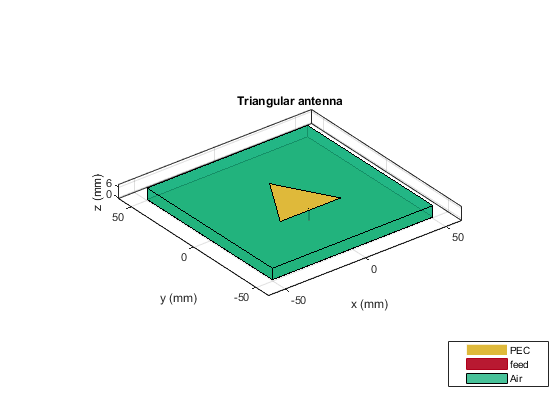

% Get the current directory
currentDir = pwd;

% Specify the subfolder name
subfolderName = 'Functions';

% Construct the full path to the subfolder
subfolderPath = fullfile(currentDir, subfolderName);

% Add the subfolder to the MATLAB path
addpath(subfolderPath);


[p_triang, p_rect, p_Circle, p_mc] = Create_Antennas();


%Plot_Antennas(p_triang, p_rect, p_Circle, p_mc);

## Generating Base Stations with a Single Antenna per Cell

In this section, we generate a specified number of base stations (`numCellSites`) with a single antenna each. The `Generate_Simple_Txs` function is used to create the base stations, and the variable `isd` represents the inter-site distance between the base stations. After creating the base stations, we assign the triangular antenna pattern `p_triang` to each base station.

numCellSites = 7;
isd = 2000;
fq=2.6e9;
txs = Generate_Simple_Txs(numCellSites, isd);
% Assign the antenna element for each cell transmitter
for tx = txs
    tx.Antenna = p_triang;
end

## Show Base Stations in Map

This section displays the base stations with a single antenna per cell on a map. The `siteviewer` function is used to create a viewer object, and the variable `mapa_osm` represents the OpenStreetMap file for the map. The `show` function is then used to display the base stations on the map.

mapa_osm="map.osm";
viewer = siteviewer("Name","SINR uma antena por cel","Basemap","openstreetmap","Buildings",mapa_osm);
viewer.Basemap = 'topographic';

show(txs);

## Display SINR map for only one Antenna

The SINR (Signal-to-Interference-plus-Noise Ratio) map is shown using the `sinr` function. The SINR map represents the signal quality and interference levels in the network. The parameters for the SINR calculation, such as bandwidth, receiver parameters, and range, are set before displaying the map.

% Define receiver parameters using Table 8-2 (b) of Report ITU-R M.[IMT-2020.EVAL] 
bw = 20e6; % 20 MHz bandwidth
rxNoiseFigure = 7; % dB
rxNoisePower = -174 + 10*log10(bw) + rxNoiseFigure;
rxGain = 0; % dBi
rxAntennaHeight = 1.5; % m

% Display SINR map
%sinr(txs,'freespace', ...
sinr(txs,'longley-rice', ...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',rxAntennaHeight, ...
    'ReceiverNoisePower',rxNoisePower, ...    
    'MaxRange',isd, ...
    'Resolution',isd/20);

## Create 8x8 Antennas Array

In this section, we create an 8x8 antennas array using the triangular antenna pattern `p_triang`. The `Create_8x8_Antennas_Array` function returns an antenna array object, which is stored in the variable `cellAntenna`. We then assign the antenna array to each base station in the `txs` array and apply downtilt to the antennas.

[cellAntenna] = Create_8x8_Antennas_Array(p_triang,fq);
% Assign the antenna array for each cell transmitter, and apply downtilt.
% Without downtilt, pattern is too narrow for transmitter vicinity.
downtilt = 15;
for tx = txs
    tx.Antenna = cellAntenna;
    tx.AntennaAngle = [tx.AntennaAngle(1); -downtilt];
end

## Display 8x8 Antennas Array radiation pattern

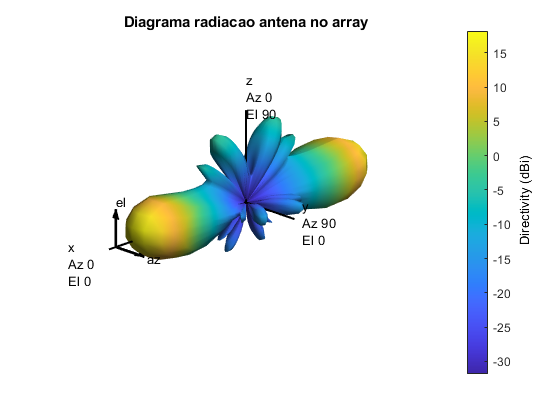

f = figure(5);
pattern(cellAntenna,fq);
polarpattern(cellAntenna,fq);
title('Diagrama radiacao antena no array');

## Display SINR map for 8x8 Antennas Array

This section shows the SINR map for the base stations with the 8x8 antennas array. Similar to the previous SINR map, we create a viewer object using the `siteviewer` function and display the base stations on the map. Then, the SINR map is calculated and displayed using the `sinr` function with appropriate parameters.

% Mostrar mapa oara array antenas 8 por 8
% Launch Site Viewer
viewer = siteviewer("Name","SINR para array 8x8 antenas","Basemap","openstreetmap","Buildings",mapa_osm);
viewer.Basemap = 'topographic';
% Show sites on a map
show(txs);

% Display SINR map
sinr(txs,'longley-rice', ...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',rxAntennaHeight, ...
    'ReceiverNoisePower',rxNoisePower, ...    
    'MaxRange',isd, ...
    'Resolution',isd/20);

## RAIN PROPAGATION MODEL

In this section, we visualize the rain propagation model on a map. We create a viewer object using the `siteviewer` function and display the map with the OpenStreetMap file represented by the variable `mapa_osm`. The `propagationModel` function is used to create a rain propagation model with a rain rate of 50 mm/h, stored in the variable `pm_rain`. The `coverage` function is then used to display the coverage of the base stations based on the rain propagation model.

viewer = siteviewer("Name","RainPropModel","Basemap","openstreetmap","Buildings",mapa_osm);
viewer.Basemap = 'topographic';

pm_rain=propagationModel('rain','RainRate',50);

% Mapa de cobertura do transmissor
coverage(txs,"PropagationModel",pm_rain)

## COVERAGE para antenas 8x8

This section displays the coverage map for the base stations with the 8x8 antennas array. Similar to previous coverage maps, we create a viewer object using the `siteviewer` function and display the map with the OpenStreet

Map file represented by the variable `mapa_osm`. The `coverage` function is used to calculate and display the coverage map for the base stations using the Longley-Rice propagation model. The signal strengths are specified in the range from -100 dBm to -60 dBm.

% Launch Site Viewer
mapa_osm="map.osm";
viewer = siteviewer("Name","Coverage","Basemap","openstreetmap","Buildings",mapa_osm);
viewer.Basemap = 'topographic';

% Mapa de cobertura do transmissor
coverage(txs,'longley-rice', 'SignalStrengths',-100:5:-60);

## Line of sight between Txs

In this section, we analyze the line of sight (LOS) between the base stations. We generate simple receivers using the `Generate_Simple_Rxs` function, which creates receivers at the same locations as the base stations. We create a viewer object using the `siteviewer` function and display the map with the OpenStreetMap file represented by the variable `mapa_osm`. Then, we use the `los` function to calculate and display the LOS between each base station and its corresponding receiver.

[rxs] = Generate_Simple_Rxs(numCellSites, isd);

rxs =   1×21 txsite array with properties:

    Name
    CoordinateSystem
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    TransmitterFrequency
    TransmitterPower



% Launch Site Viewer
mapa_osm="map.osm";
viewer = siteviewer("Name","LOS between Base Stations","Basemap","openstreetmap","Buildings",mapa_osm);
viewer.Basemap = 'topographic';

show(txs)
show(rxs)
for tx = txs
    los(tx, rxs)
end

## BEST TX

In this section, we find the best transmitter for a specific receiver location. We create a receiver object, `rx`, at a specified location. We create a viewer object using the `siteviewer` function and display the map with the OpenStreetMap file represented by the variable `mapa_osm`. Then, we find the best transmitter among the base stations for the receiver location based on signal strength. The link margin, a measure of communication robustness, is calculated as the difference between the receiver sensitivity and the received power. Finally, we display the link between the receiver and the best transmitter on the map.

%Receiver
rx = rxsite('Name','Casa carlos', ...
       'Latitude',39.74120, ...
       'Longitude',-8.81476);

mapa_osm="map.osm";
viewer = siteviewer("Name","BestTx","Basemap","openstreetmap","Buildings",mapa_osm);
viewer.Basemap = 'topographic';
show(rx);
show(txs);

%Distancia entre antenas
dm = distance(txs,rx) % Unit: m

dm = 	1.0e+03 *

    0.6974    0.6974    0.6974    2.7016    2.7016    2.7016    2.4119    2.4119    2.4119    1.7451    1.7451    1.7451    1.3063    1.3063    1.3063    1.7722    1.7722    1.7722    2.4408    2.4408    2.4408


dkm = dm / 1000;

%Angulo entre antenas
azFromEast = angle(txs,rx); % Unit: degrees counter-clockwise from East
azFromNorth = -azFromEast + 90; % Convert angle to clockwise from North

% Find Best Tx
max_value=-200; % Potencia recebida 
for tx = txs 
    ss = sigstrength(rx,tx);
    if(ss>max_value)
        best_tx=tx;
        max_value=ss;
    end
end

% Link margin ( uma métrica da robustes da comunicação, calculado
% subtraindo a sensividade do recetor e a potencia recebida
margin = abs(rx.ReceiverSensitivity - ss);

fprintf("Link Margin:\t%f\n", margin);

Link Margin:	79.940791



% Link de comunicações no mapa
link(rx,best_tx);

## HANDOVER

This section simulates a handover scenario for a mobile receptor. It generates a series of latitude and longitude coordinates representing the movement of the mobile receptor. The `siteviewer` function is used to create a viewer object and display the map with the OpenStreetMap file represented by the variable `mapa_osm`. We show the base stations on the map and iterate through each coordinate to simulate handover. For each coordinate, we create a receiver object, calculate the signal strengths from two base stations, determine the best base station, and display the link between the receiver and the best base station on the map.

latitudes_mobile=[39.739006,39.738719,39.738315,39.737893,39.737529,39.737018,39.736676,39.736125,39.73564,39.735,39.7344,39.73404,39.73364,39.733560,39.733470,39.733526,39.733707,39.7341];
% Get the latitudes of points 7 and 8
lat_8 = latitudes_mobile(9);
lat_9 = latitudes_mobile(10);
% Create 10 equally spaced points between lat_8 and lat_9
new_lats = linspace(lat_8,lat_9,20);
% Insert the new points into the latitudes_mobile vector
latitudes_mobile = [latitudes_mobile(1:9), new_lats(2:end-1), latitudes_mobile(10:end)];

longitudes_mobile=[-8.817274,-8.815051,-8.814523,-8.814,-8.813384,-8.812783,-8.812316,-8.811591,-8.810848,-8.810,-8.809421,-8.808913,-8.8077,-8.807259,-8.80663,-8.806145,-8.805375,-8.8043];
% Get the latitudes of points 7 and 8
long_8 = longitudes_mobile(9);
long_9 = longitudes_mobile(10);
% Create 10 equally spaced points between lat_8 and lat_9
new_longs = linspace(long_8,long_9,20);
% Insert the new points into the latitudes_mobile vector
longitudes_mobile = [longitudes_mobile(1:9), new_longs(2:end-1), longitudes_mobile(10:end)];

% mapa_osm="map.osm";
% viewer = siteviewer("Name","HandOver","Basemap","openstreetmap","Buildings",mapa_osm);
% viewer.Basemap = 'topographic';
% % -8.807632630982194 -------------
% centerSite = txsite('Name','MathWorks Glasgow', ...
%     'Latitude',39.74422,...
%     'Longitude',-8.80763);

%Show sites on a map
%show(txs);

handover_pot=zeros(1,14);

%number_steps=length(latitudes_mobile);
number_steps=36;

for i=1:number_steps

    %Casa 39.74120486553289, -8.814761942942786
    rx = rxsite('Name','Carro 1', ...
           'Latitude',latitudes_mobile(i), ...
           'Longitude',longitudes_mobile(i));
    %show(rx)

    %Distancia entre antenas
    dm = distance(txs,rx); % Unit: m
    dkm = dm / 1000;

    %Angulo entre antenas
    azFromEast = angle(txs,rx); % Unit: degrees counter-clockwise from East
    azFromNorth = -azFromEast + 90; % Convert angle to clockwise from North

    % Potencia recebida 
    max_value=-200;

    tx_to_test=[txs(13), txs(16)];
    j=0;
    for tx = tx_to_test 
        j=j+1;
        ss = sigstrength(rx,tx);
        handover_pot(i,j)=ss;
        if(ss>max_value)
            best_tx=tx;
            max_value=ss;
        end
    end    
    % Link margin ( uma métrica da robustes da comunicação, calculado
    % subtraindo a sensividade do recetor e a potencia recebida
    %margin = abs(rx.ReceiverSensitivity - ss);

    % Link de comunicações no mapa
    %link(rx,best_tx);
end

## Graph the handover and the overlapping power of the antennas

The received power values and overlapping power of the antennas are graphed in this section.

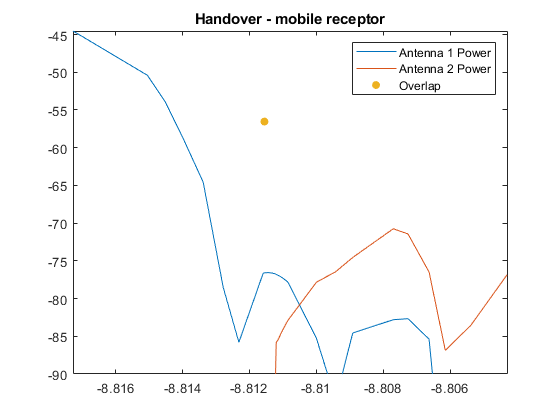

f = figure(10);
x=1:1:number_steps;
plot(longitudes_mobile,handover_pot(:,1))
ylim([-90 inf]);
hold on
plot(longitudes_mobile,handover_pot(:,2))
xlim([min(longitudes_mobile) max(longitudes_mobile)])
title("Handover - mobile receptor");

scatter(-8.81155, -56.536, 'filled')
legend('Antenna 1 Power', 'Antenna 2 Power', 'Overlap')

hold off

## Network Capacity Study

In this section, we study the network capacity based on various parameters. We set the number of base stations, number of users, number of channels, bandwidth per channel, and other factors. We calculate the number of users that can be served by the base stations and determine the number of additional small cells needed to serve the remaining users. Finally, we display the results of the capacity study.

numCellSites=7;

num_hab=60e3;
taxa_util_sim=0.1;
taxa_pen_merc=0.3;
taxa_add_tech=0.9;

hab_servir=num_hab*taxa_util_sim*taxa_pen_merc*taxa_add_tech;

num_channels=3;
bandwith_channel=20e6;
bandwith_channel_2=25e6;
ncol=8;
nrow=8;

num_users=numCellSites*3;
num_users=num_users*(ncol*nrow)/2;

left_users=hab_servir-num_users;

num_small_cells=ceil(left_users/32);

fprintf("Número de Utilizadores Simultáneos:\t%d\n", hab_servir);

Número de Utilizadores Simultáneos:	1620


fprintf("Número de Macro Cells Utilizadas:\t%d\n", numCellSites);

Número de Macro Cells Utilizadas:	7


fprintf("Número de Utilizadores servidos por Macro Cells:\t%d\n", num_users);

Número de Utilizadores servidos por Macro Cells:	672


fprintf("Número de Utilizadores restantes sem serviço (áreas mais densas):\t%d\n", left_users);

Número de Utilizadores restantes sem serviço (áreas mais densas):	948


fprintf("Número de Pico Cells recomendadas:\t%d\n", num_small_cells);

Número de Pico Cells recomendadas:	30


## Stage 2

This script contains the code about the Stage 2 of this work related to Localized coverage simulation (broadband simulation)

Main_Etapa_2